# BME 2740 Interactive Lecture 11

# By: Dr. Asad Mirza

# Adapted From: Dr. Ilmar Tamames

## Numerical Integration

#### Static vs Dynamic

The study of mathematical models of the world shows us that there are two general classes of phenomena:

**Static**: Describes a unknown number given an input


$$x^3 -{7x}^2 +41=0$$


**Dynamic**: Describe a unknown function given an input


$$\frac{dx}{dt}=2xt$$


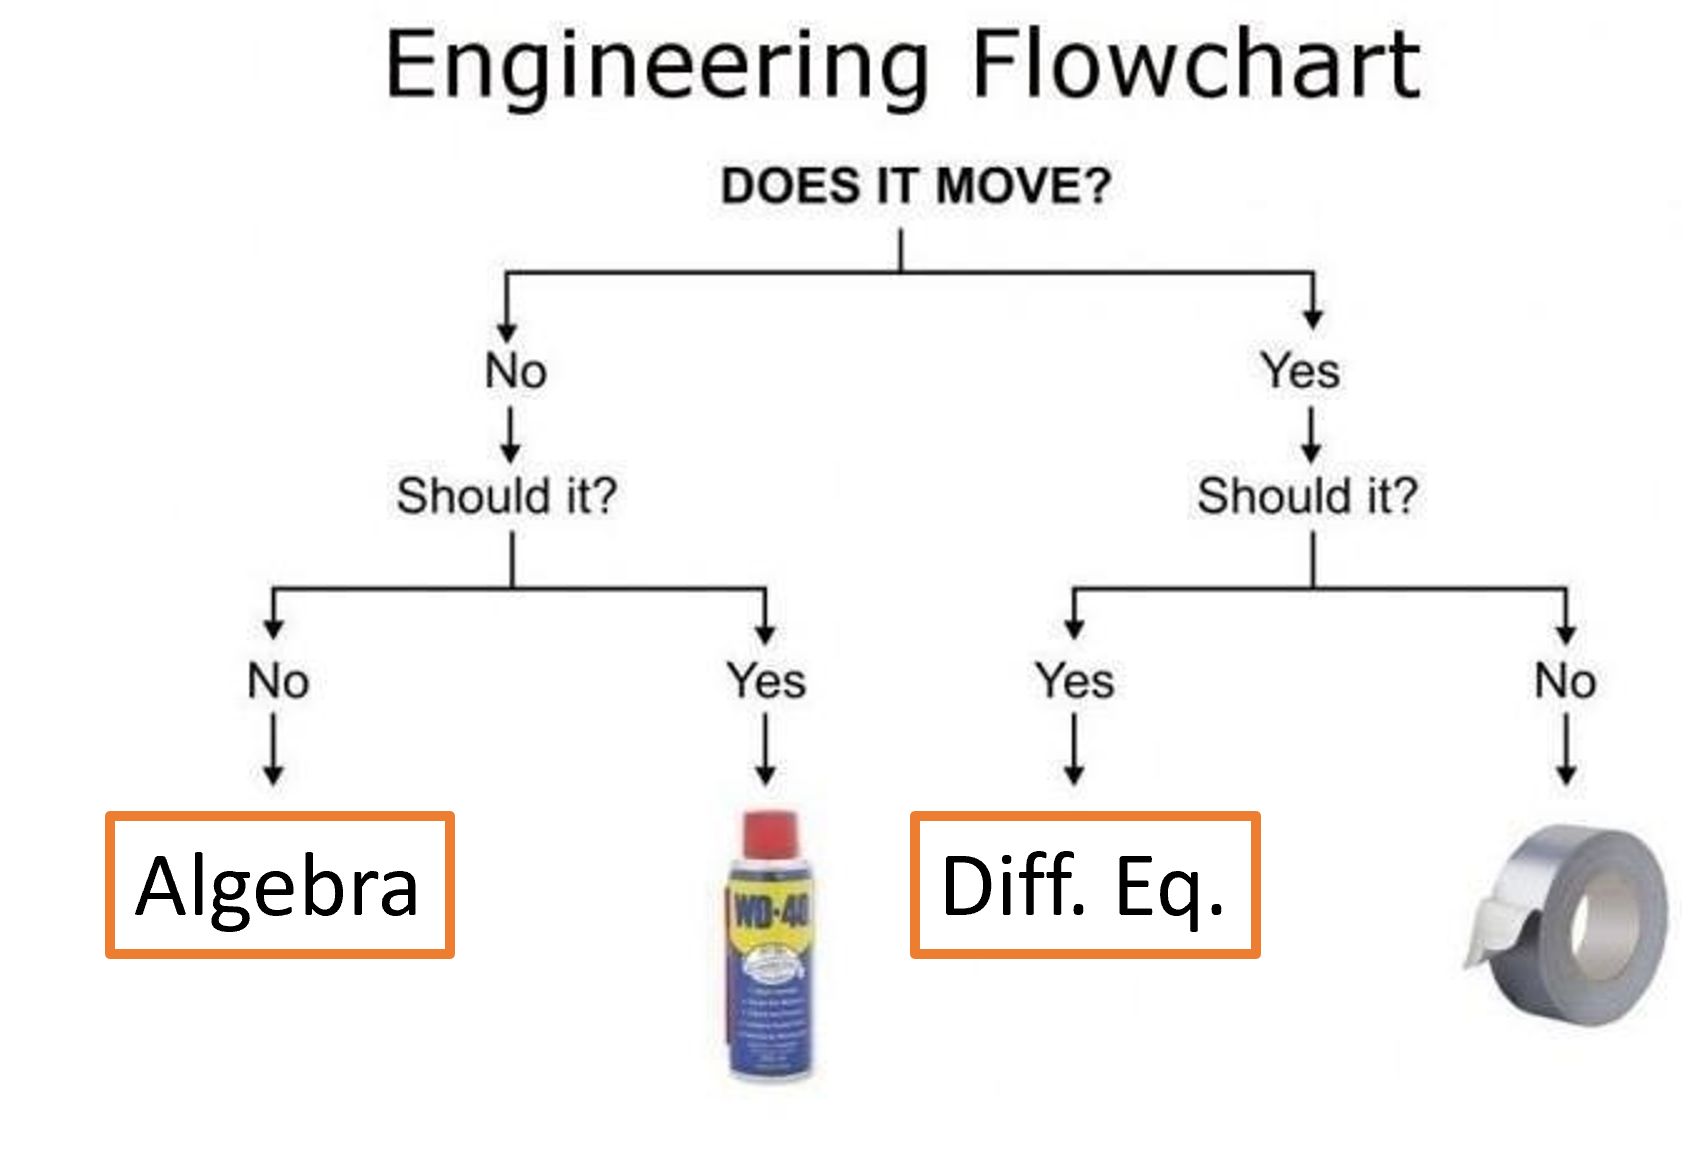

Unfortunately, most interesting physiological phenomena are dynamic.

In algebra (static) we normally seek unknown **numbers** – in numerical integration (dynamic) we normally seek unknown **functions.**

#### Derivative

The derivative of a function represents an infinitesimal change in the function with respect to one of its variables.


$$F=\mathit{ma}=m*\frac{\mathit{dv}}{\mathit{dt}}=m*\frac{d^2 s}{dt^2 }$$


**Differential Equation**

A differential equation is any equation that contains derivatives, either ordinary derivatives (ODE) or partial derivatives (PDE).


$$a\;{y^{\prime } }^{\prime } +b\;y^{\prime } +c\;y=g\left(t\right)\to \mathrm{Lagrange}\;\mathrm{Prime}\;\mathrm{Notation}$$



$$\sin \left(y\right)\frac{d^2 y}{dx^2 }=\left(1-y\right)\frac{\mathit{dy}}{\mathit{dx}}+y^2 \to \mathrm{Leibniz}\;\mathrm{Notation}$$



$$3\overset{\cdots \cdot }{y} +10\overset{\cdots }{y} +4\;\ddot{y} =\cos \left(t\right)\to \textrm{Newton’s}\;\textrm{Dot}\;\textrm{Notation}\;$$



$$\frac{\partial^2 u}{\partial x^2 }=\frac{\partial u}{\partial t}\to \mathrm{Partial}\;\mathrm{Derivative}\;\mathrm{Notaiton}\;\mathrm{from}\;\mathrm{Legendre}\;\mathrm{and}\;\mathrm{Jacobi}$$


#### First Order Differential Equations

There is no general method that solves every possible differential equation, but there are methods to solve types of them.

- Separation of variables

- First-order, homogeneous linear equation

- First-order, non-homogeneous linear equation

- Bernoulli

- Exact

- Exact, integrating factor method

- Laplace Transforms

- And many more

The problem with this is that these are the exceptions rather than the rule. The **vast** majority of differential equations you find in the real world can’t be solved so easily.

#### Approximating Differential Equations

There are many times we will need to compute derivatives, but we may not have closed-form expressions for them.

- Unsolvable derivatives.

- Derivatives on the computer in simulation.

- Derivatives when the function is unknown (like raw data).

#### Finite Differences

Just as we used different techniques to approximate integrals, we can use finite differences to approximate differential equations.

The three we will cover are known as the forward, backward, and central finite difference schemes.

Forward difference


$$f^{\prime } {\left(x\right)}\;\cong \lim_{h\to 0} \frac{f{\left(x+h\right)}\;-f\left(x\right)}{h}$$


Backward difference


$$f^{\prime } {\left(x\right)}\;\cong \lim_{h\to 0} \frac{f{\left(x\right)}\;-f\left(x-h\right)}{h}$$


Centered difference 


$$f^{\prime } {\left(x\right)}\;\cong \lim_{h\to 0} \frac{f{\left(x+h\right)}\;-f\left(x-h\right)}{2h}$$


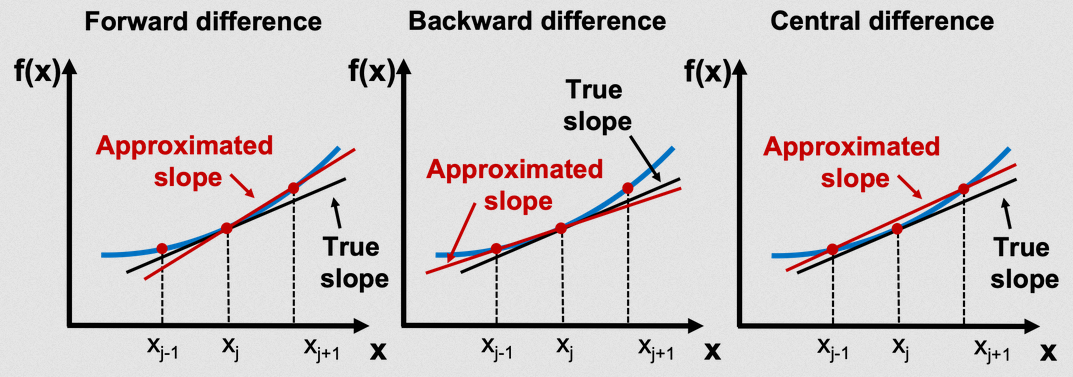

#### Example 1

You are a biotech consultant for Innatech Inc. and you have been given the latest data from their clinical trial of a drug designed to treat stress. They present you with an index comprised of various stress biomarkers. They are interested in reducing the magnitude of index oscillations and ask you to determine the rate of change of the index per hour since delivering the drug.

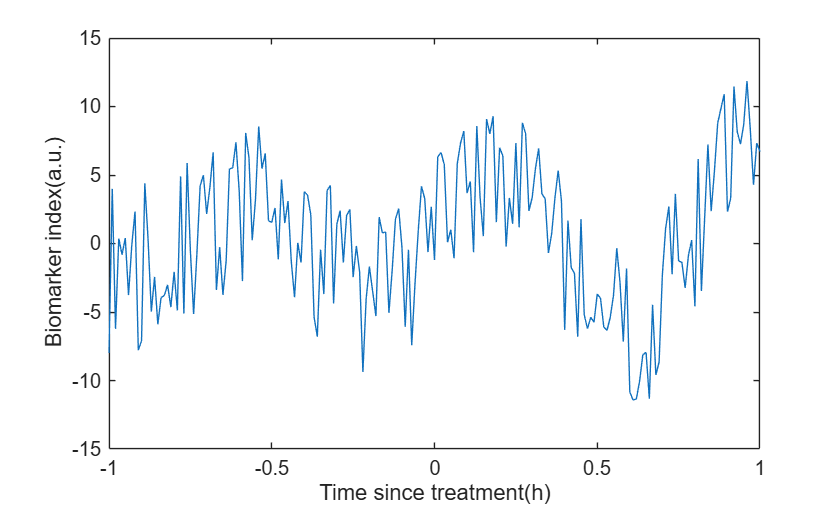

%Set up
Time= -1:.01:1;
% Random variable of with noise added to it.
Biomarker=4*sin(8*Time).*2.^Time;
Noise_data=.6*randi([-10 10],1,length(Time));
Biomarker=Biomarker+Noise_data;
plot(Time,Biomarker)
xlabel("Time since treatment(h)");
ylabel("Biomarker index(a.u.)");

Notice the noise in the function, taking the derivative of the original function would be straightforward but not with all this noise embedded in it.

#### Forward Difference

Consider the Taylor series approximation of a function from lecture 4:


$$f{\left(x\right)}=f{\left(a\right)}+\frac{f^{{\left(1\right)}} {\left(a\right)}\left(x-a\right)}{1!}+\frac{f^{{\left(2\right)}} {\left(a\right)}{\left(x-a\right)}^2 }{2!}+\frac{f^{{\left(3\right)}} {\left(a\right)}{\left(x-a\right)}^3 }{3!}+\ldots$$


Solve for the first derivative term, $f^{{\left(1\right)}} {\left(a\right)}$


$$f^{{\left(1\right)}} {\left(a\right)}\left(x-a\right)=f{\left(x\right)}-f{\left(a\right)}-\frac{f^{{\left(2\right)}} {\left(a\right)}{\left(x-a\right)}^2 }{2!}-\frac{f^{{\left(3\right)}} {\left(a\right)}{\left(x-a\right)}^3 }{3!}-\ldots$$



$$f^{{\left(1\right)}} {\left(a\right)}=\frac{f{\left(x\right)}-f{\left(a\right)}}{\left(x-a\right)}-\frac{f^{{\left(2\right)}} {\left(a\right)}{\left(x-a\right)} }{2!}-\frac{f^{{\left(3\right)}} {\left(a\right)}{\left(x-a\right)}^2 }{3!}-\ldots$$


Replacing $h=x-a$.


$$f^{{\left(1\right)}} {\left(a\right)}\cong \frac{f{\left(a+h\right)}-f{\left(a\right)}}{h}+\textrm{𝑂}\left(h\right)$$
 

Which is the Forward difference from before. $O\left(h\right)$ is known as the Big-O notation and it describes how fast an error term (or function) grows relative to another as the variable approaches a limit (often zero or infinity). In this context, it refers to the remaining or neglected terms in an approximation that are smaller in magnitude than the main terms kept. Here, it describes how the error scales linearly with $h$: if $h$ is 10x smaller, the error becomes 10x smaller.

% Array of example values
x=[1 2 3 4 5];
% Some easy function
y=x.^2;
% Real derivative of y(x)
dy=2*x;                                                     % >> This is the EXACT derivative, dy= 2*x
% Derivative using forward finite differences by hand
dFForward1=[y(2)-y(1), y(3)-y(2), y(4)-y(3), y(5)-y(4)]    % >> This is the APPROX* derivative , # of intervals = #x - 1

dFForward1 =      3     5     7     9




% % Option 1: matrix option
h=x(2)-x(1);  %Calculates the step wise
dFForward2=(y(2:end)-y(1:end-1))/h 

dFForward2 =      3     5     7     9


% y(2:end) select all values except the first
%y(1:end-1) select all the values except the last
% Subtract the two arrays
% The division by h converts the differences into approximate derivative
% values

% % Option 2: using diff command

% Usually we have the same step size so diff(x)=h
DiffCommand=diff(y)./diff(x)

DiffCommand =      3     5     7     9


% diff(y) calculates differences between consecutive y-values, giving [3 5 7 9].
% diff(x) calculates differences between consecutive x-values, giving [1 1 1 1].
% diff(x) calculates differences between consecutive xx-values, giving [1 1 1 1].

The error rate is too big, our analytical result is not matching our Forward Finite Differences. 

Compare the results: 

- **Exact values** (`dy` `=` `2*x`): `[2` `4` `6` `8` `10]`

- **Forward finite** differences by hand (`dFForward1`): `[3` `5` `7` `9]`

- **Matrix option** (`dFForward2`): `[3` `5` `7` `9]`

- **Diff command** (`DiffCommand`): `[3` `5` `7` `9]` 

#### Centered difference

But what if we use a combined approach or centered differencing?

Look at the forward point


$$f{\left(a+h\right)}=f{\left(a\right)}+\frac{f^{{\left(1\right)}} {\left(a\right)}\left(a+h-a\right)}{1!}+\frac{f^{{\left(2\right)}} {\left(a\right)}{\left(a+h-a\right)}^2 }{2!}+\frac{f^{{\left(3\right)}} {\left(a\right)}{\left(a+h-a\right)}^3 }{3!}+\ldots$$



$$f{\left(a+h\right)}=f{\left(a\right)}+\frac{f^{{\left(1\right)}} {\left(a\right)}h}{1!}+\frac{f^{{\left(2\right)}} {\left(a\right)}h^2 }{2!}+\frac{f^{{\left(3\right)}} {\left(a\right)}{\left(h\right)}^3 }{3!}+\ldots$$


Look at the backward point


$$f{\left(a-h\right)}=f{\left(a\right)}+\frac{f^{{\left(1\right)}} {\left(a\right)}\left(a-h-a\right)}{1!}+\frac{f^{{\left(2\right)}} {\left(a\right)}{\left(a-h-a\right)}^2 }{2!}+\frac{f^{{\left(3\right)}} {\left(a\right)}{\left(a-h-a\right)}^3 }{3!}+\ldots$$



$$f{\left(a-h\right)}=f{\left(a\right)}+\frac{f^{{\left(1\right)}} {\left(a\right)}\left(-h\right)}{1!}+\frac{f^{{\left(2\right)}} {\left(a\right)}{\left(-h\right)}^2 }{2!}+\frac{f^{{\left(3\right)}} {\left(a\right)}{\left(-h\right)}^3 }{3!}+\ldots$$


Subtract backward from forward point


$$f{\left(a+h\right)}-f{\left(a-h\right)}={2hf}^{{\left(1\right)}} {\left(a\right)}-2\frac{f^{{\left(3\right)}} {\left(a\right)}h^3 }{3!}+\ldots$$


Solve for the first derivative $f^{{\left(1\right)}} {\left(a\right)}$


$$f^{{\left(1\right)}} {\left(a\right)}=\frac{f{\left(a+h\right)}-f{\left(a-h\right)}}{2h}+\frac{f^{{\left(3\right)}} {\left(a\right)}h^2 }{3!}+\frac{f^{{\left(5\right)}} {\left(a\right)}h^4 }{5!}\ldots$$



$$f^{{\left(1\right)}} {\left(a\right)}=\frac{f{\left(a+h\right)}-f{\left(a-h\right)}}{2h}+\textrm{𝑂}\left(ℎ^2 \right)$$


% Array of example values
x=[1,2,3,4,5];
% Some easy function
y=x.^2;
% Real derivative of y(x)
dy=2*x;


% Central finite difference by hand
dFCentered1=[y(3)-y(1), y(4)-y(2), y(5)-y(3)]/2

dFCentered1 =      4     6     8


% It calculates the derivative at the interior points x=2,3,4x=2,3,4, 
% using the function values on either side of each point.
% ex. 3-1 is for 2    


% % Option 1: matrix option
h=x(2)-x(1);
dFCentered2=(y(3:end)-y(1:end-2))/(2*h)'

dFCentered2 =      4     6     8


% y(3:end) start at 3rd element to the last
% y(1:end-2) start at 1st element to third-to-last 

% Option 2: using gradient command
gradient(y,x); % approximates the derivative at every point using centered differences for ||interior|| points
% The first and last elements use forward differences
% We care only about the interior points in central difference


% Let's look at forward difference again
h=x(2)-x(1); %stepwise
dFForward2=(y(2:end)-y(1:end-1))/h 

dFForward2 =      3     5     7     9


% y(2:end) selects the second element through the last element of y
% y(1:end-1) selects the first element through the second-to-last element.

%As you can see the two endpoints match

Gradient works best with equidistant x values. Use diff otherwise. Meaning $\mathrm{diff}\left(x\right)\approx h$

- Exact derivative: [2 4 6 8 10]

- Centered difference by hand: [4 6 8]

- Centered difference matrix option: [4 6 8]

- gradient command: [3 4 6 8 9]

Back to our example 1:

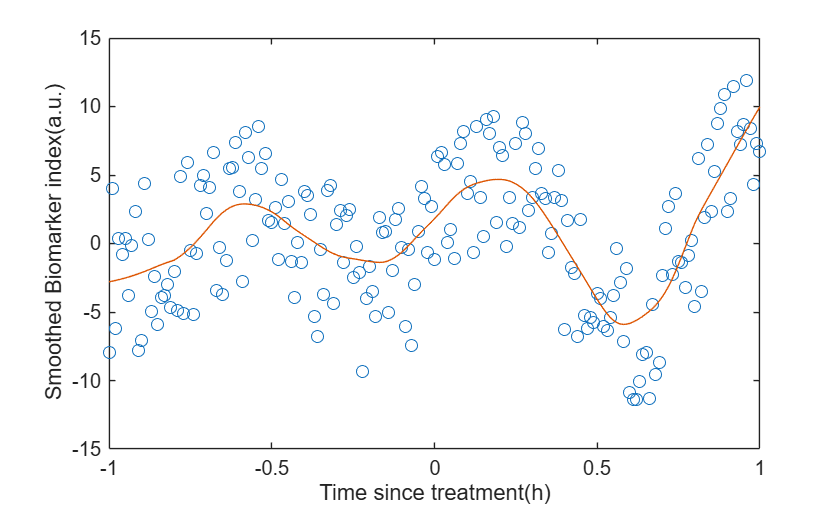

% Smooth data to simplify sample
% BiomarkerSmoothed = smooth(Biomarker, 0.2,'loess'); <<< Got broke, shows
% error:
% LOESS smoothing without toolboxes
x = (1:length(Biomarker))';
y = Biomarker(:);

span = 0.2;
n = length(y);
BiomarkerSmoothed = zeros(n,1);

windowSize = max(3, ceil(span*n));

for i = 1:n
    % Select nearest points
    [~, idx] = sort(abs(x - x(i)));
    idx = idx(1:min(windowSize,n));

    % Local coordinates
    dx = x(idx) - x(i);
    dy = y(idx);

    % Tricube weights
    dmax = max(abs(dx));
    if dmax == 0
        w = ones(size(dx));
    else
        w = (1 - (abs(dx)/dmax).^3).^3;
    end

    % Weighted local linear regression
    X = [ones(length(dx),1), dx];
    W = diag(w);

    beta = (X' * W * X) \ (X' * W * dy);
    BiomarkerSmoothed(i) = beta(1);
end

% Loess means local regression using a 2nd degree polynomial smoothing.
% The idea is it to use x percentage of total points per fit in a slide
% moving window. Here, we use 0.2 or 20% of the data during each interval
% to find the best fitting quadratic. 
% Imagine doing a moving polyfit(x,y,2) every 20% of points.
plot(Time,Biomarker,'o')
hold on
plot(Time,BiomarkerSmoothed)
xlabel("Time since treatment(h)");
ylabel("Smoothed Biomarker index(a.u.)");

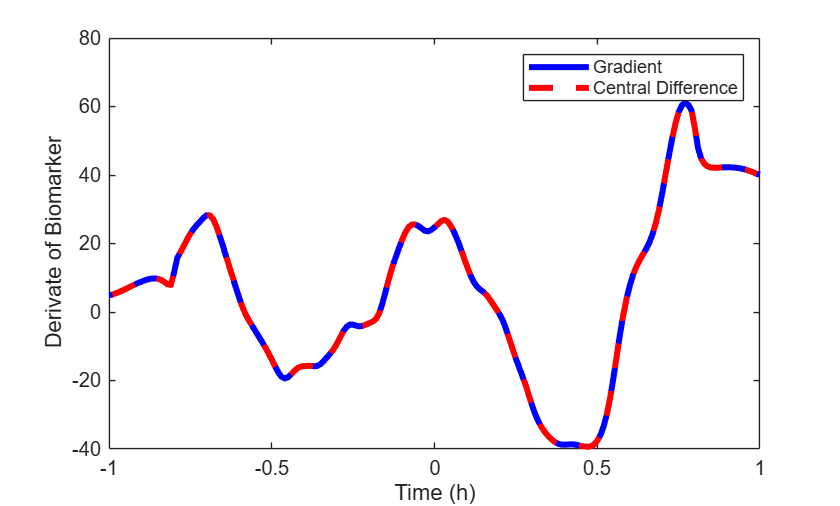

% Time step
h = Time(2)-Time(1); %stepwise
% Central difference method
dFCentered=(BiomarkerSmoothed(3:end)-BiomarkerSmoothed(1:end-2))/(2*h)'; 

% Add to graph
figure
% Plotting
Time= -1:.01:1;
plot(Time,gradient(BiomarkerSmoothed,Time),'b-','LineWidth',3)

% "gradient(BiomarkerSmoothed,Time)"
% Estimates the derivative numerically using MATLAB's built-in gradient function.

hold on 
plot(Time(2:end-1),dFCentered,'r--','LineWidth',3)
ylabel("Derivate of Biomarker");
xlabel("Time (h)");
legend("Gradient","Central Difference")

TIP: [Smooth](https://www.mathworks.com/help/curvefit/smooth.html?s_tid=doc_ta)

#### Example 2

After analyzing the data, the Innotechscience staff produce the following model:


$$BI=sin{\left(8t\right)}e^{-t} +4$$


Given this new hypothesis, the team now requests you evaluate how confident you are in your estimate of the true derivative at the time of drug administration.


$$\frac{d}{\mathit{dt}}sin{\left(8t\right)}e^{-t} +4$$


[Wolframalpha](https://www.wolframalpha.com/input?i2d=true&i=Divide%5Bd%2Cdt%5D%5C%2840%29sin8t+*+Power%5Be%2C-t%5D%2B4%5C%2841%29+)

[Microsoft Solve](https://mathsolver.microsoft.com/en/solve-problem/%60displaystyle%60frac%7Bd%7D%7Bd%20t%20%20%7D%20%20%60left(%20%60sin%20(%20%208t%20%20%20)%20%20%20%7B%20e%20%20%7D%5E%7B%20-t%20%20%7D%20%20%2B4%20%60right))

[Symbolab](https://www.symbolab.com/solver/calculus-calculator/%5Cfrac%7Bd%7D%7Bdx%7D%5Cleft(sin%5Cleft(8t%5Cright)%5Ccdot%20e%5E%7B-t%7D-4%5Cright)?or=input)


$$\frac{\mathit{dB}I}{\mathit{dt}}=e^{-t} \left(8\;\cos \left(8t\right)-\sin \left(8t\right)\right)$$


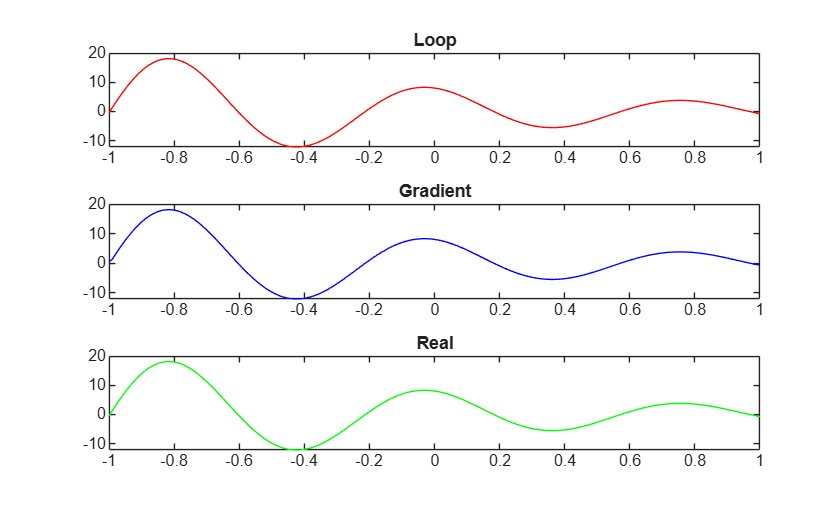

% Set up time vector
Time= -1:.01:1;
% Anonymous function
f = @(t) sin(8*t).*exp(-t)+4;
% Actual derivative of function
df= @(t) exp(-t).*(8*cos(8*t)-sin(8*t));
%Calculate step size
h = Time(2)-Time(1);

% Find the gradient (derivative of the function, f)
% Option 1: Loop
dFCentered1 = zeros(length(Time),1);
for k = 1:length(Time)
    xForward=Time(k)+h;
    xBack=Time(k)-h;
    dFCentered1(k) = (f(xForward)- f(xBack) )/(2*h);
end

%Option 2: Using gradient
dFCentered2 =gradient(f(Time),Time);
%Plotting
subplot(3,1,1);
plot(Time,dFCentered1,'r');
title("Loop");
subplot(3,1,2);
plot(Time,dFCentered2,'b')
title("Gradient");
subplot(3,1,3);
plot(Time,df(Time),'g')
title("Real");

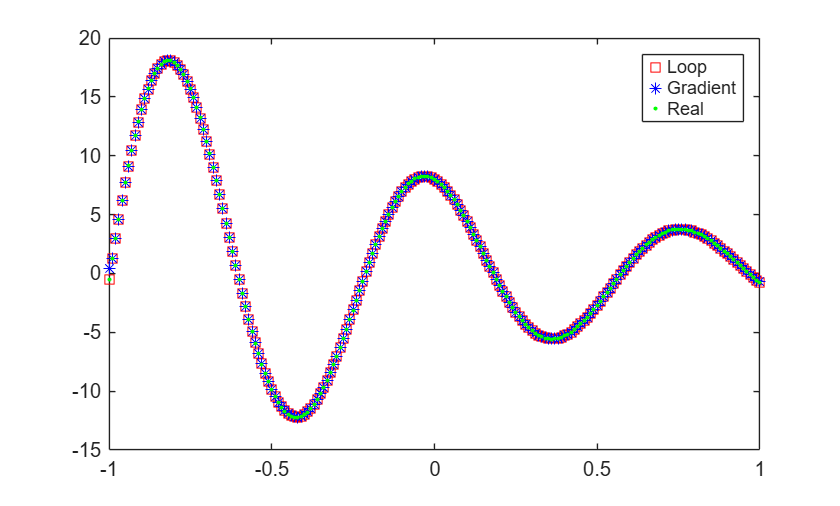

figure
%Plotting
plot(Time,dFCentered1,'rs');
hold on
plot(Time,dFCentered2,'b*')
plot(Time,df(Time),'g.')
legend('Loop','Gradient','Real')

TIP: [Subplot](https://www.mathworks.com/help/matlab/ref/subplot.html)

#### Convergence

How do you know the optimum value for h?

Just like how when we did numerical integration we had diminishing returns for smaller h we have a similar situation for derivatives.

figure
% Instead of a linear spacing we are using a logarithm spacing
% linspace(1,10,10)=10 linearly spaced values from 1 to 10=[1 2 3 4 5 6 7 8 9 10]
% logspace(1,10,10)=10 log spaced values from 10^1 to 10^10=[10^1 10^2 10^3...]
% Small h: 0.001
% Large h: 0.1
% There are 100 values in between.
h = logspace(-3,-1,100)

h =     0.0010    0.0010    0.0011    0.0011    0.0012    0.0013    0.0013    0.0014    0.0015    0.0015    0.0016    0.0017    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0027    0.0028    0.0029    0.0031    0.0032    0.0034    0.0035    0.0037    0.0039    0.0040    0.0042    0.0044    0.0046    0.0049    0.0051    0.0053    0.0056    0.0059    0.0061    0.0064    0.0067    0.0071    0.0074    0.0077    0.0081    0.0085    0.0089    0.0093    0.0098


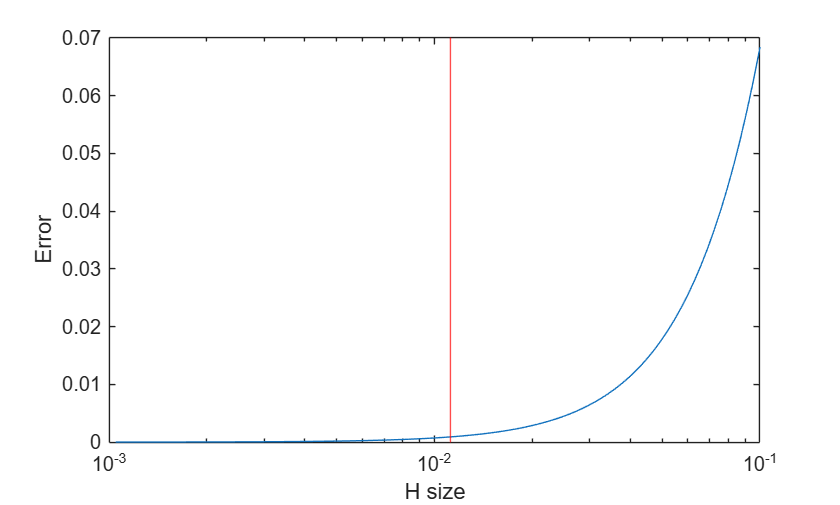

f = @(x) sin(8*x).*exp(-x)+4; % f(x)= sin(8x)*e^−x  + 4

% % Step 1
% Pre-allocation
dFCentered = zeros(length(h),1); % This creates a column vector containing 100 zeros
% We use it to store the derivative approximations calculated for each step size. 
% Pre-allocation also avoids repeatedly resizing the array inside the loop.

% % Step 2
% Central finite difference, in this case at the specific point of x=0
for k = 1:length(h)
    dFCentered(k) = (f(0+h(k)) - f(0-h(k)) )/(2*h(k));
end

% f(0+h(k)) evaluates the function just to the right of zero.
% f(0-h(k)) evaluates the function just to the left of zero
% After the loop, dFCentered contains one derivative approximations for each value of h, so 100 in this case

% % Step 3
% Find error between each two terms in dFCentered
dError = abs(diff(dFCentered));
%calculates how much each derivative approximation differs from the next one.


% % Step 4
% Plot with x axis being on a log scale
semilogx(h(2:end),dError)
xlabel("H size");
ylabel("Error");


% % Step 5 Find where estimated error is closest to tolerance and display
% Let's say we're fine with an error of 1e-3
tol=0.001;  % find where the estimated error is closest to this tolerance
% We can ask MATLAB to find the step size where that happened
[min_val, min_ind_loc]=min(abs(dError-tol));
% Let's mark it
xline(h(min_ind_loc),'r')

% And display it
fprintf("H of %3.5f\n", h(min_ind_loc))

H of 0.01123


TIP: [Logspace](https://www.mathworks.com/help/matlab/ref/logspace.html?s_tid=doc_ta)

TIP: [Semilogx](https://www.mathworks.com/help/matlab/ref/semilogx.html?s_tid=doc_ta)